Physical constants

G = 6.673e-11; % universal gravitational constant, m3 * kg-1 * s-2
M_E = 5.9722e24 ; % mass of the Earth, kg
R = 6371008.8; % radius of the Earth, m
Omega_E = 2*pi / 86400; % earth's rotation in rad / s

Omega_E_vector = [0;0;Omega_E]; % angular velocity vector for Earth's rotation in the ECI coordinate system

Effect of observation altitude to the range of a eavesdropping sensor in relation to different elevation angles of the terminal.

d = @(h,ele)(h ./ (tand(ele)) / 1000); % maximum range in kilometers

Let's plot d for elevation range of 10 deg to 90 deg and observation altitude in range of 100 meters to 20 km.

ele = 10:2.5:85; % elevation angle in degrees
h = 0:750:20000; % aircraft altitude in meters

[H, E] = meshgrid(h, ele);

s = surf(E, H, d(H, E));

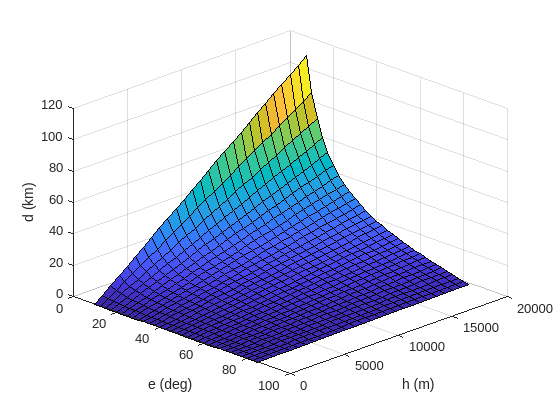

view(45,30);
ax = ancestor(s, 'axes');
ax.YAxis.Exponent = 0;
ax.ZAxis.Exponent = 0;
%ax.YLim = [0,20000];
%ax.XLim = [5,95];

xlabel('e (deg)');
ylabel('h (m)');
zlabel('d (km)');

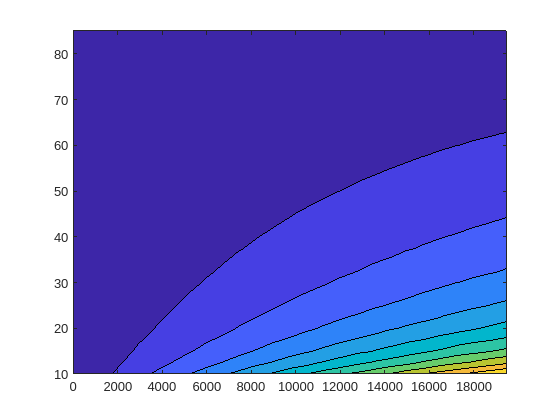

contourf(H,E,d(H,E));

Orbital radius in relation to velocity of the sub-satellite point (in km/s).

v_air = @(h,r_orbit)( (h+R) .* sqrt( (G*M_E) ./ (r_orbit + R).^3 ) );

Plot the velocity for orbital radius in range of 500 km to 37000 km. Difference in the observing aircraft's altitude has a very minor influence on the velocity and can be ignored in the calculation (Earth's radius dominates)

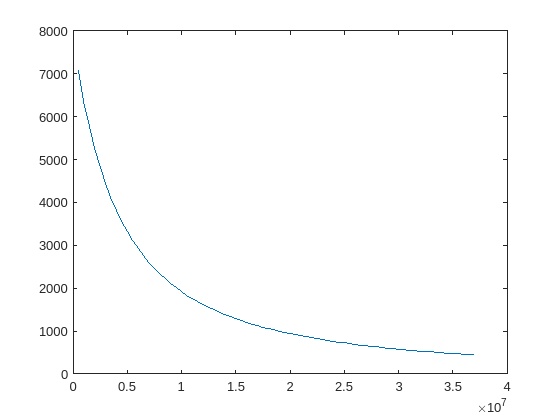

r_orbit = 500e3:500e3:37e6;

[H_air, R_orbit] = meshgrid(h, r_orbit);

p_v_air = plot(r_orbit, v_air(10000,r_orbit));

In the case of GEO, Earth's rotation cancels the velocity of the sub-satellite point. Next, we will evaluate the effect of orbital period and inclination to the velocity of the sub-satellite point. We setup the orbits in the ECI coordinate system and account for the Earth's rotation by converting to ECF.

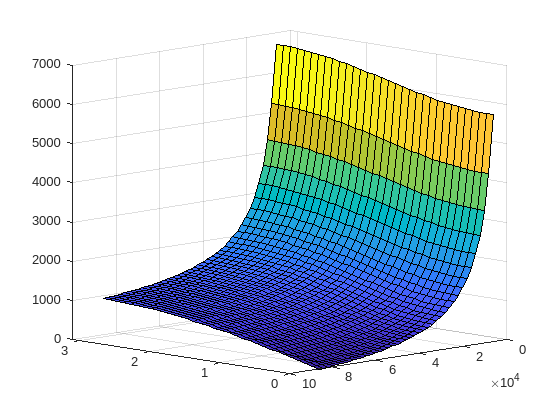

inclination = 0:0.1:pi; % inclination in rad
orbital_period = 6400:2000:86400; % in seconds

roty = @(t)[cos(t) 0 sin(t); 0 1 0; -sin(t) 0 cos(t)] ;

omega_ECF_magnitude = @(i, T)( norm(roty(i) * ( (2*pi / T) .* [0;0;1] ) - Omega_E_vector));

[I_orbit, T_orbit] = meshgrid(inclination, orbital_period);

omega_arr = arrayfun(omega_ECF_magnitude, I_orbit, T_orbit);

v_air_arr = R .* omega_arr;

s_omega_ECF_norm = surf(I_orbit, T_orbit, v_air_arr);
view(-135,10);